# Taller 5

### 15/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 4 y 5*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Notas frente al uso de los métodos:*

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

### Interpolación y Aproximación

*Desarrollaremos el sexto taller, para esta sección resolveremos *$1,3,4,5,7,8,9,10\;y\;11$.

**1. **Se tienen las cesantias en los distintos fondos a febrero 16 de 2021:

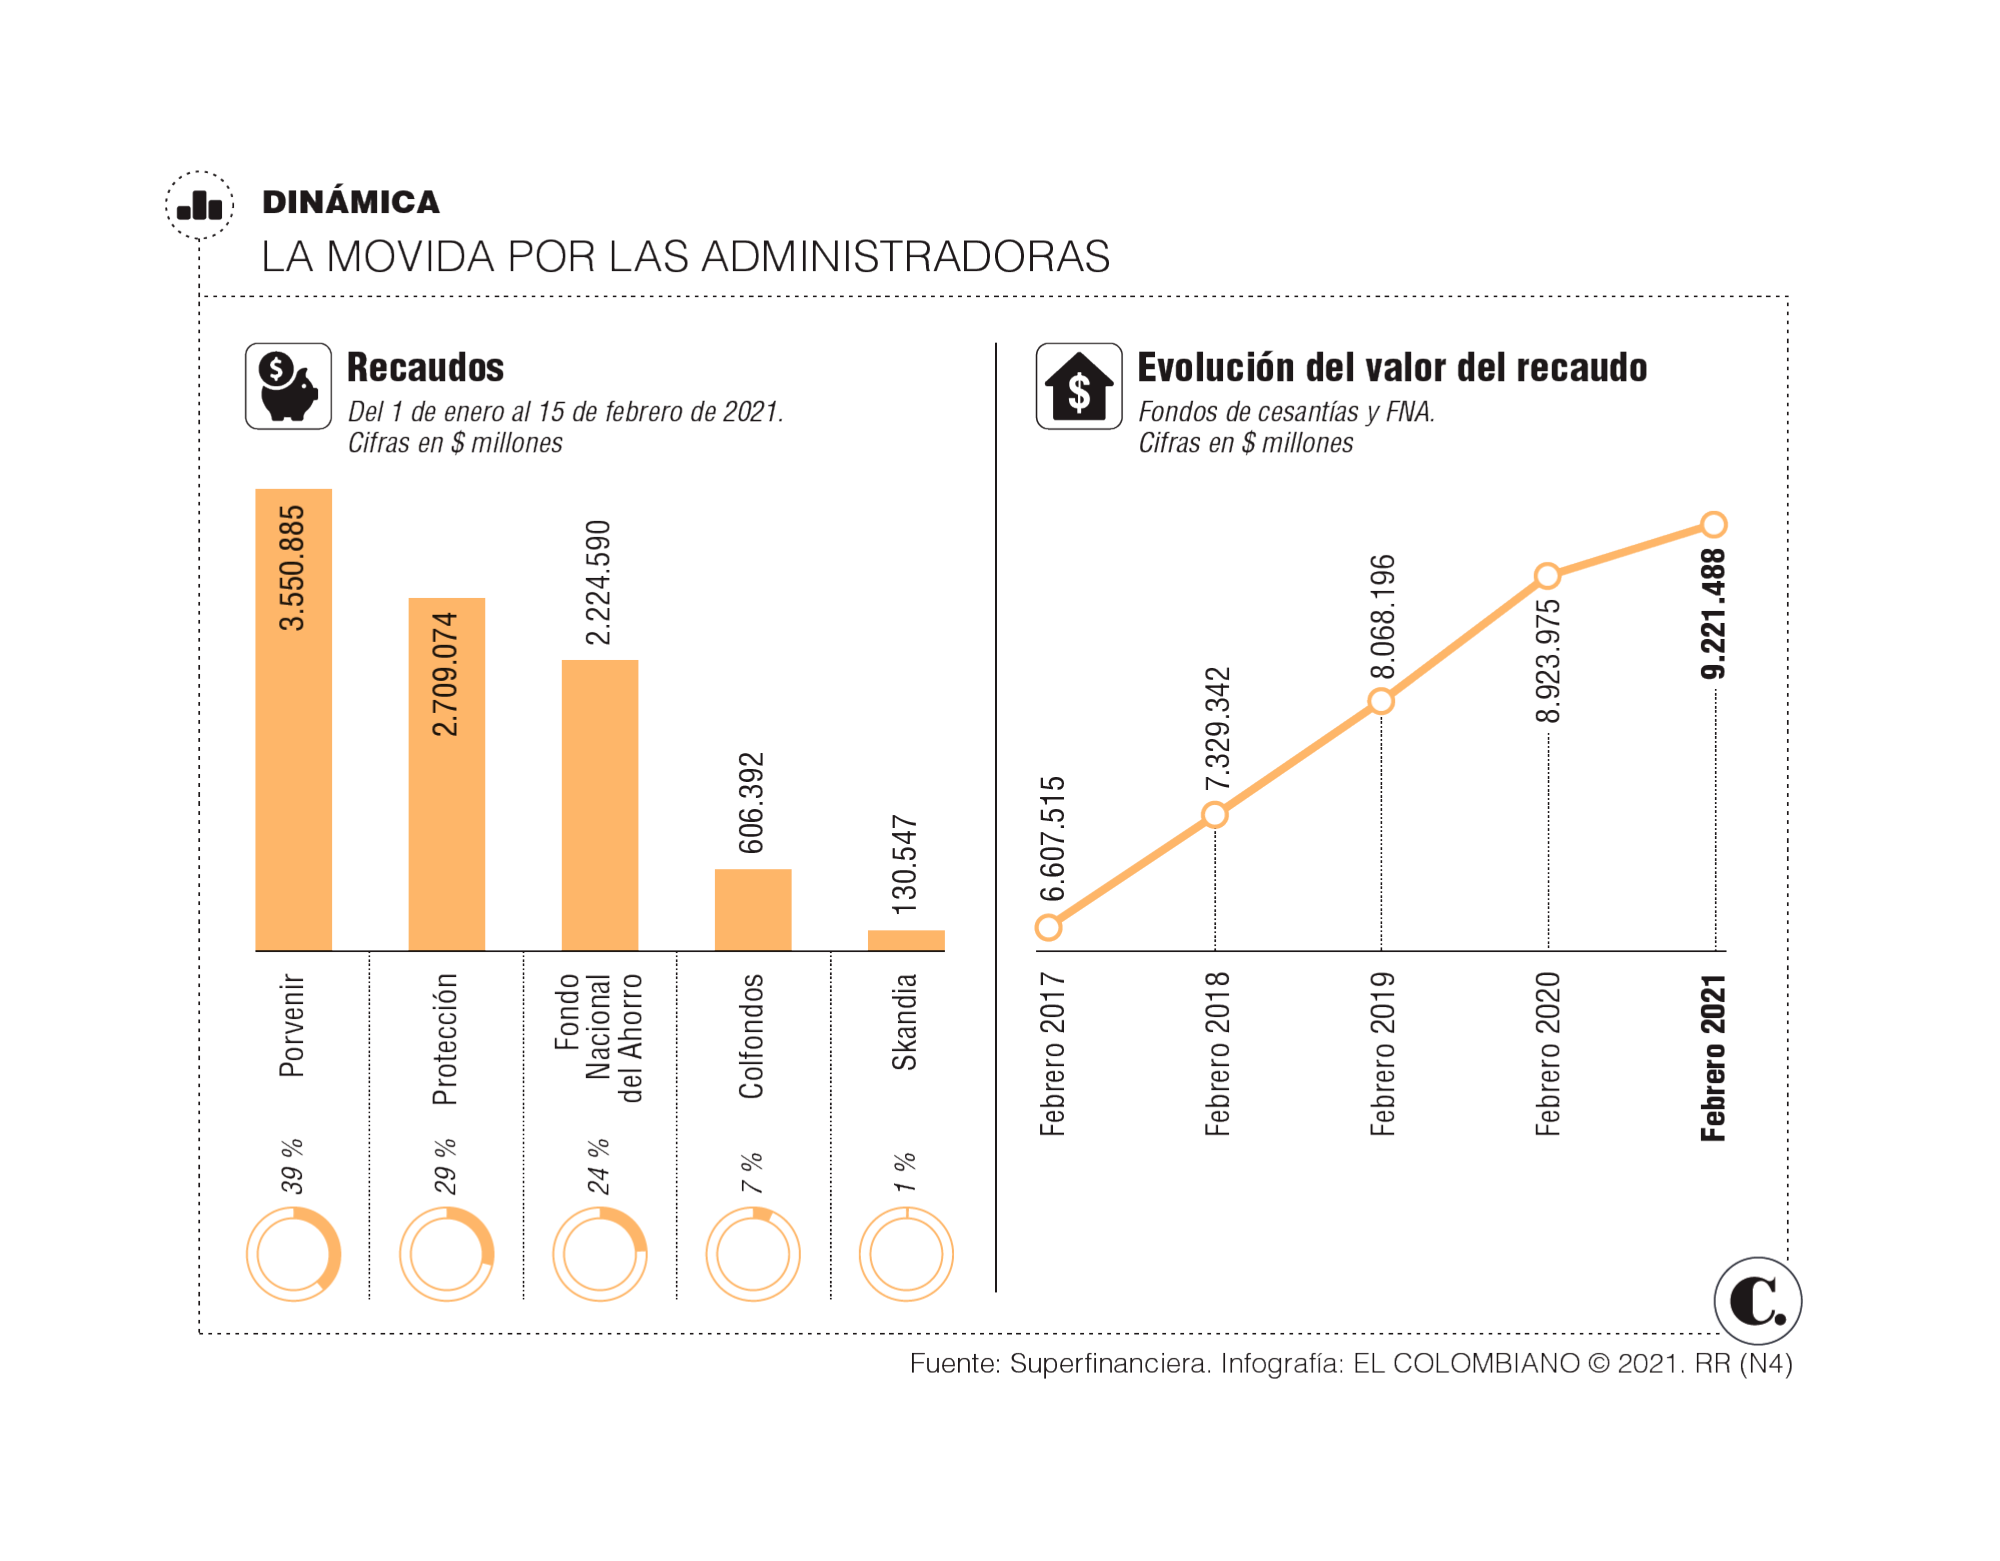

clear
syms x

X = 2017:2021;
Y = [6607.515 7329.342 8068.196 8923.975 9221.488];

**    a) **Encuentre el polinomio de grado 2 que interpola los datos correspondientes a los años 2017, 2018, 2019:

help newpoly

  Entrada   - X es un vector que contiene la lista de abscisas
            - Y es un vector que contiene la lista de ordenadas
  Saldia    - C es un vector que contiene los coeficientes del
              polinomio interpolante de Newton
            - D es la tabla de diferencias divididas



[C, D] = newpoly(X(1:3), Y(1:3));

P = @(x) polyval(C, x);
P(2017), Y(1)

ans = 6.6075e+03

ans = 6.6075e+03

**   b) **Evalue este en el año 2020, y comparelo con el verdadero:

P(2020), Y(4)

ans = 8.8241e+03

ans = 8.9240e+03

**   c) **Encuentre el polinomio de grado 2 que interpola los datos correspondientes a los años 2018, 2019, 2020:

C = newpoly(X(2:4), Y(2:4));

P = poly2sym(C, x);

digits(4)
disp(vpa(P))

$$58.46\,x^{2}-2.353e+5\,x+2.367e+8$$

**   d) **Encuentre el polinomio de grado 4 que interpola los cinco puntos de la gráfica:

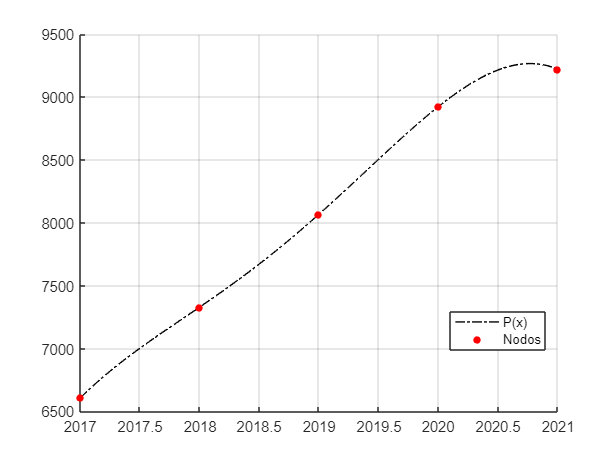

C = newpoly(X, Y);
P = @(x) polyval(C, x);

clf('reset')
hold on
fplot(P, [X(1), X(end)], '-.k', 'DisplayName', 'P(x)')
plot(X, Y, '.R', 'MarkerSize', 15, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

**3) **En cada caso considere la tabla $\left\lbrack x_j ,f\left(x_j \right)\right\rbrack$. Para la tabla obtenga el polinomio interpolante de grado a lo más $n$ por el método de Lagrage y encuentre la cota para el error absoluto que resulta al interpolar el intervalo $\left\lbrack x_0 ,x_n \right\rbrack$:

    **a) **$f\left(x\right)=e^{2\;x} \;\cos \left(3\;x\right),$    $x_0 =0,x_1 =0\ldotp 3,x_2 =0\ldotp 6,n=2$

    **b) **$f\left(x\right)=\textrm{sen}\left(\log \left(x\right)\right),$    $x_0 =2,x_1 =2\ldotp 4,x_2 =2\ldotp 6,n=2$

    **c) **$f\left(x\right)=\cos \left(x\right)\;+\;\sin \left(x\right),$    $x_0 =0,x_1 =0\ldotp 25,x_2 =0\ldotp 5,{\;x}_3 =\;1,n=3$

clear
syms f(x)

f(x) = sin(log(x));
f = matlabFunction(f);

X = [2 2.4 2.6]; Y = f(X);

[L, C] = lagran(X, Y)

L =    -0.1306    0.8970   -0.6325


C =     4.1667  -20.8333   26.0000
  -12.5000   57.5000  -65.0000
    8.3333  -36.6667   40.0000


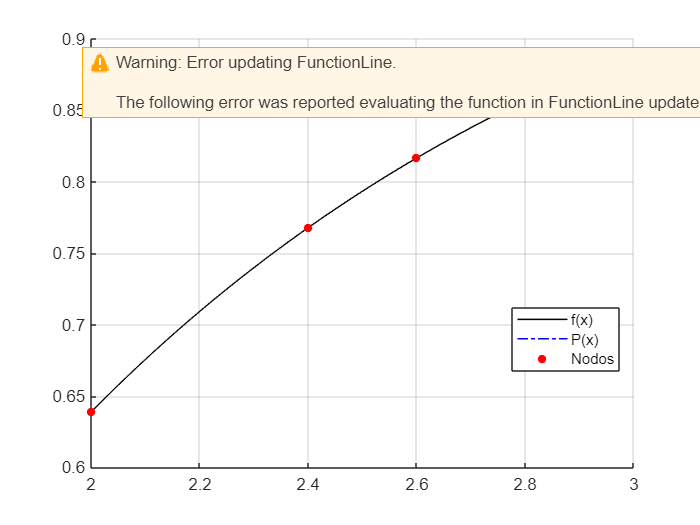

P = @(x) polyval(C, x);

clf('reset')
hold on
fplot(f, [X(1), 3], 'k', 'DisplayName', 'f(x)')
fplot(P, [X(1), 3], '-.b', 'DisplayName', 'P(x)')
plot(X, Y, '.R', 'MarkerSize', 15, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

% Solución Númerica
format short
X = linspace(X(1), X(end), 1e5);
E = P(X) - f(X);
norm(E, 'inf')

ans = 6.8350e-04

Recordemos que el error de cualquier polinomio interpolante a lo más $n$ con nodos selectos, es de:


$$E\left(x\right)=\frac{f^{\left(n+1\right)} \left(\xi \left(x\right)\right)}{\left(n+1\right)!}\;\prod_{i=0}^n \left(x-x_i \right)$$


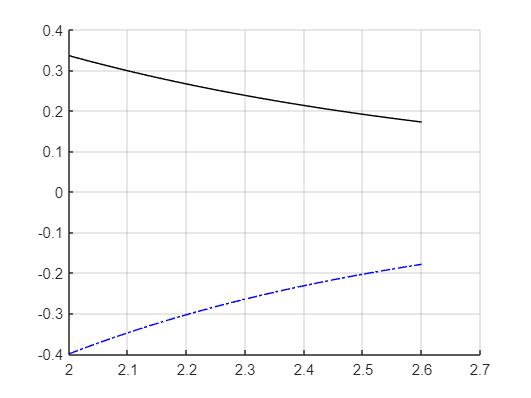

% Solución Analitica
clear
syms f(x)

f(x) = sin(log(x));
d3f(x) = diff(f, x, 3);
d4f(x) = diff(f, x, 4);

f = matlabFunction(f);
d3f = matlabFunction(d3f);
d4f = matlabFunction(d4f);

X = [2 2.4 2.6]; Y = f(X);

clf('reset')
hold on
fplot(d3f, [X(1), X(end)], 'k', 'DisplayName', 'd3f(x)')
fplot(d4f, [X(1), X(end)], '-.b', 'DisplayName', 'd4f(x)')
grid on
hold off

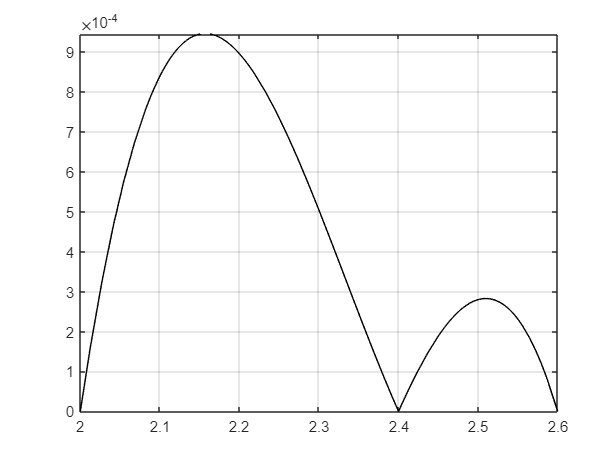

maxd3f = X(1);

E(x) = abs(d3f(X(1)) / factorial(2 + 1) * (x - X(1)) * (x - X(2)) * (x - X(3)));
clf('reset')
fplot(E(x), [X(1), X(end)], 'k', 'DisplayName', 'E(x)')
grid on

**4. **Sea $f\left(x\right)=e^x$ , $0\le x\le 2\ldotp$ 

**Nota:** El polinomio interpolante es único. Puede usar el método de Lagrange o el método de Newton *(diferencias divididas).*

clear

f = @(x) exp(x);

**a) **Aproxime $f\left(\ldotp 25\right)$ usando interpolación lineal con $x_0 =0$, $x_1 =\ldotp 5$.

X = [0 .5]; Y = f(X);
C = lagran(X, Y);

polyval(C, .25), f(.25)

ans = 1.3244

ans = 1.2840

**c) **Aproxime $f\left(\ldotp 25\right)$ y $f\left(\ldotp 75\right)$ usando interpolación con $x_0 =0$, $x_1 =1$, $x_2 =2$.

X = [0 1 2]; Y = f(X);
C = lagran(X, Y);

polyval(C, .25), f(.25)

ans = 1.1528

ans = 1.2840

polyval(C, .75), f(.75)

ans = 2.0119

ans = 2.1170

**5. **Considere la siguiente tabla de diferencias divididas obtenida a partir de los valores de $f\left(x\right)=x^5 -x^4 +2x^2 +1$ en los puntos $-2,-1,0,1,2,3y\;4$:

                                                                                                                     −2      −39 

                                                                                                                     −1       1           40

                                                                                                                     0         1           0            −20 

                                                                                                                     1         3           2            1             7 

                                                                                                                     2         25         22           10          3          -1 

                                                                                                                     3        181       156          67         19         4         1 

                                                                                                                     4        801        620         232        55        9         1         0 

Utilice esta tabla para construir polinomios interpolantes para f(x) en:

**a.    **$x=-1,0,1$**    d.    **$x=-1,0,1,2,3,4$**    e. **$x=0,1$

clear

C = [1 -1 0 2  0 1];
F = @(x) polyval(C, x);
P2 = @(x) 1 + 0 * (x - -1) + 1 * (x - -1) * (x - 0);

P5 = @(x) P2(x) + 3 * (x - -1) * (x - 0) * (x - 1) + 4 * (x - -1) * (x - 0) * (x - 1) * (x - 2) + 1 * (x - -1) * (x - 0) * (x - 1) * (x - 2) * (x - 3);
F(3), P5(3)

ans = 181

ans = 181

P = @(x) P2(x) + 3 * polyval(poly([-1 0 1]), x) + 4 * polyval(poly([-1 0 1 2]), x) + 1 * polyval(poly([-1 0 1 2 3]), x);
P(3)

ans = 181

**7. **Use el teorema del error al interpolar para encontrar una cota del máximo error que se comete en el intervalo $\left\lbrack 0,\pi \right\rbrack$ cuando usamos el polinomio interpolante $P_2 \left(x\right)$ para aproximar $f\left(x\right)\;=\;\cos \left(\pi \;x\right)$ en los nodos $x_0 =0$, $x_1 =\pi /2$, $x_2 =\pi$.

clear

f = @(x) cos(pi * x);

X = [0 pi/2 pi];
Y = f(X);

C = newpoly(X, Y);
P = @(x) polyval(C, x);

X0 = linspace(0, pi, 1e2);
E = P(X0) - f(X0);

Error = norm(E, 'inf')

Error = 1.5573

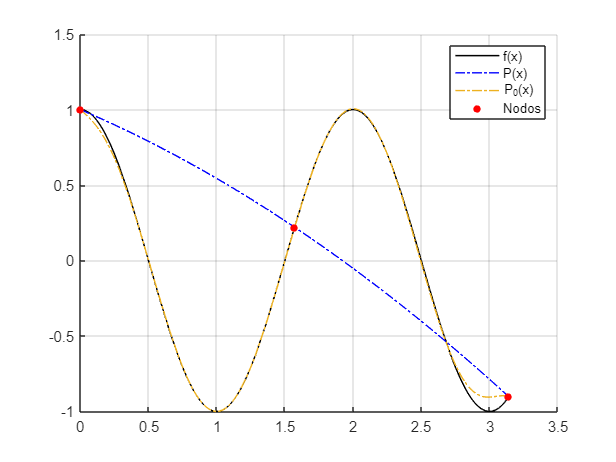

X0 = linspace(0, pi, 8);
C0 = newpoly(X0, f(X0));
P0 = @(x) polyval(C0, x);

clf('reset')
hold on
fplot(f, [X(1), X(end)], 'k', 'DisplayName', 'f(x)')
fplot(P, [X(1), X(end)], '-.b', 'DisplayName', 'P(x)')
fplot(P0, [X(1), X(end)], '-.', 'DisplayName', 'P_0(x)')
plot(X, Y, '.r','MarkerSize', 15, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

**11. **Para una función $f$ el método interpolante de Newton basado en diferencias divididas encuentra que el polinomio interpolante en los nodos $x_0 =0,x_1 =0\ldotp 25,x_2 =0\ldotp 5,x_3 =0\ldotp 75,$ es $P\left(x\right)=1+4x+4x\;\left(x-0\ldotp 25\right)+\frac{16}{3}x\;\left(x-0\ldotp 25\right)\;\left(x-0\ldotp 5\right)$.

**a) **Complete la tabla de diferencias divididas.

**b) **Encuentre $f\left(0\ldotp 75\right)$. Observe que este valor se puede encontrar evaluando el polinomio $P$ en $0\ldotp 75$ o tambíen como uno de los números que encontró completando la tabla. 

clear

X = 0:.25:.75;

D = zeros(4) + diag([1 4 4 16/3]);
D(4, 3) = D(4, 4) * ( X(4) - X(4 - 4 + 1) ) + D(3, 3);
D(3, 2) = D(3, 3) * ( X(3) - X(3 - 3 + 1) ) + D(2, 2);
D(2, 1) = D(2, 2) * ( X(2) - X(2 - 2 + 1) ) + D(1, 1);
D(4, 2) = D(4, 3) * (X(4) - X(4 - 3 +1)) + D(3, 2);
D(3, 1) = D(3, 2) * (X(3) - X(3 - 2 +1)) + D(2, 1);
D(4, 1) = D(4, 2) * (X(4) - X(4 - 2 +1)) + D(3, 1)

D =     1.0000         0         0         0
    2.0000    4.0000         0         0
    3.5000    6.0000    4.0000         0
    6.0000   10.0000    8.0000    5.3333


El valor que buscamos es:

D(4, 1)

ans = 6

P = @(x) 1 + 4 * x + 4 * polyval(poly([0, .25]), x) + 16/3 * polyval(poly([0, .25 .5]), x);
P(.75) % Valor que esperamos hallar.

ans = 6

### **Sobre los nodos de Chebyshev**

Utilice los ceros del polinomio de Chebyshev de grado 3 para obtener polinomios interpolantes de grado 2 para las siguientes funciones definidas en el intervalo$\left\lbrack -1,1\right\rbrack$.

$f\left(x\right)=\log \left(x+2\right)$.

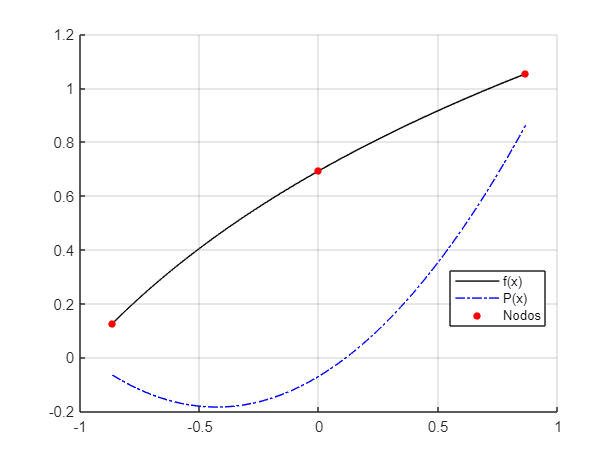

clear

f = @(x) log(x + 2);

[C, X, Y] = cheby(f, 2, -1, 1);
X = fliplr(X); Y = fliplr(Y); 

clf('reset')
hold on
fplot(f, [X(1), X(end)], 'k', 'DisplayName', 'f(x)')
fplot(@(x) polyval(C, x), [X(1), X(end)], '-.b', 'DisplayName', 'P(x)')
plot(X, Y, '.r','MarkerSize', 15, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

chebyT = @(x) [chebyshevT(0, x), chebyshevT(1, x), chebyshevT(2, x)] * C';

clf('reset')
hold on
fplot(f, [X(1), X(end)], 'k', 'DisplayName', 'f(x)')
fplot(chebyT, [X(1), X(end)], '-.b', 'DisplayName', 'P(x)')

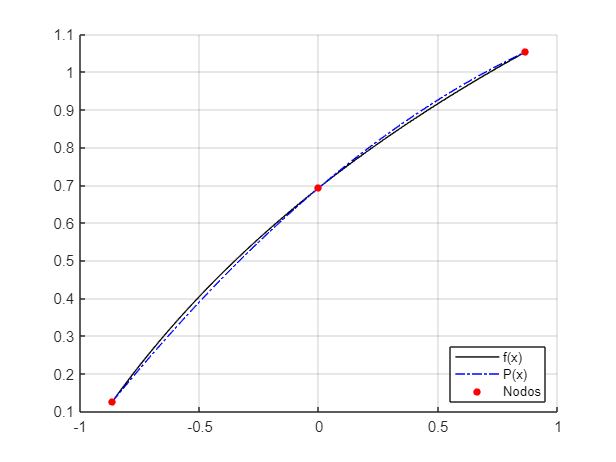

plot(X, Y, '.r','MarkerSize', 15, 'DisplayName', 'Nodos')
legend('Location','best')
grid on
hold off

clear
syms x
[chebyshevT(0, x), chebyshevT(1, x), chebyshevT(2, x), chebyshevT(3, x)]

$$ans = \left(\begin{array}{cccc} 1 & x & 2\,x^{2}-1 & 4\,x^{3}-3\,x \end{array}\right)$$